%% ELEC5305 – ML Pipeline for FM Parameter Prediction
% This live script: synthesizes a small FM dataset, extracts features,
% trains regressors to predict (r, I), re-synthesizes with predicted params,
% and evaluates with MAE/R2 and log-STFT spectral loss.

%% Setup
clear; clc;
fs  = 16000;            % sample rate
dur = 0.8;              % seconds
fc  = 440;              % A4
outAudio = "results/audio";
outPlots = "results/plots";
outML    = "results/ml";
if ~exist(outAudio,"dir"), mkdir(outAudio); end
if ~exist(outPlots,"dir"), mkdir(outPlots); end
if ~exist(outML,"dir"), mkdir(outML); end

%% Utility: FM synth + ADSR (inline to keep script self-contained)
fm_synth_local = @(fc,r,I,dur,fs) normalize( ...
    sin(2*pi*fc*(0:1/fs:dur-1/fs).' + I*sin(2*pi*(r*fc)*(0:1/fs:dur-1/fs).')) , "range",[-1 1]);

% Simple linear ADSR helper (optional use)
function a = adsr_local(env, dur, fs)
A=round(env.A*fs); D=round(env.D*fs); R=round(env.R*fs); S=env.S;
N=round(dur*fs); Slen=max(0,N-(A+D+R));
a=[linspace(0,1,A), linspace(1,S,D), S*ones(1,Slen), linspace(S,0,R)]; a=a(:); a=a(1:N);
end

%% 1) Build / Load Dataset
% Option A: synthesize grid (recommended for reproducibility)
rs   = [0.5 1 2];                   % fm/fc ratios
Is   = [0 2 4 6];                   % modulation index
env  = struct('A',0.02,'D',0.06,'S',0.8,'R',0.15);
useADSR = true;                    % true to apply ADSR

X = [];              % features
Y = [];              % targets [r, I]
Wavs = {};           % for optional listening

for r = rs
    for I = Is
        % ---- synth tone ----
        x = fm_synth_local(fc, r, I, dur, fs);
        if useADSR
            a = adsr_local(env, dur, fs);
            x = x .* a;
        end
        % save example audio (optional)
        fname = sprintf("%s/fm_grid_fc%d_r%.2g_I%.2g.wav", outAudio, fc, r, I);
        audiowrite(fname, x, fs);
        Wavs{end+1} = fname; %#ok<SAGROW>

        % ---- features ----
        feat = extract_features_local(x, fs);
        X = [X; feat]; %#ok<AGROW>
        Y = [Y; r, I]; %#ok<AGROW>
    end
end

fprintf("Dataset size: %d samples. Feature dim: %d.\n", size(X,1), size(X,2));

Dataset size: 12 samples. Feature dim: 30.


%% 2) Split Train/Test
cv  = cvpartition(size(X,1), 'HoldOut', 0.3);
Xtr = X(training(cv),:);   Ytr = Y(training(cv),:);
Xte = X(test(cv),:);       Yte = Y(test(cv),:);

%% 3) Train Light Regressors (predict r and I)
mdl_r = fitrlinear(Xtr, Ytr(:,1), 'Learner','leastsquares', 'Lambda',1e-2);
mdl_I = fitrlinear(Xtr, Ytr(:,2), 'Learner','leastsquares', 'Lambda',1e-2);

Yhat_te = [ predict(mdl_r, Xte), predict(mdl_I, Xte) ];

% Metrics
MAE = mean(abs(Yhat_te - Yte), 1);
R2  = 1 - sum((Yhat_te - Yte).^2, 1) ./ sum((Yte - mean(Yte,1)).^2, 1);
fprintf('MAE_r=%.3f, MAE_I=%.3f | R2_r=%.3f, R2_I=%.3f\n', MAE(1), MAE(2), R2(1), R2(2));

MAE_r=0.492, MAE_I=2.044 | R2_r=0.300, R2_I=-1.083


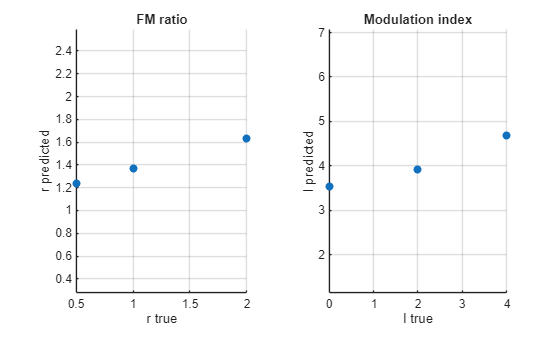


% Scatter plots
tiledlayout(1,2);
nexttile; scatter(Yte(:,1), Yhat_te(:,1), 'filled'); grid on; axis equal;
xlabel('r true'); ylabel('r predicted'); title('FM ratio');
nexttile; scatter(Yte(:,2), Yhat_te(:,2), 'filled'); grid on; axis equal;
xlabel('I true'); ylabel('I predicted'); title('Modulation index');
saveas(gcf, fullfile(outPlots, 'ml_scatter_true_vs_pred.png'));

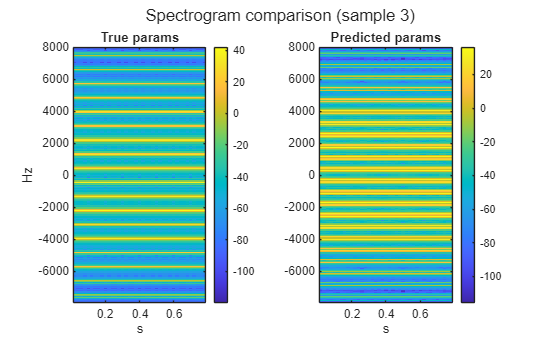

%% 4) End-to-end Re-synthesis & Spectral Loss (log-STFT L1)
nSel = min(12, size(Xte,1));
idx  = randperm(size(Xte,1), nSel);
losses = zeros(nSel,1);

for k = 1:nSel
    r0 = Yte(idx(k),1);  I0 = Yte(idx(k),2);
    r1 = Yhat_te(idx(k),1); I1 = Yhat_te(idx(k),2);

    x0 = fm_synth_local(fc, r0, I0, dur, fs);
    x1 = fm_synth_local(fc, r1, I1, dur, fs);

    % STFT
    wlen = round(0.04*fs); hop = round(0.02*fs); nfft = 2^nextpow2(wlen);
    [S0, F, T] = stft(x0, fs, 'Window',hann(wlen,'periodic'), 'OverlapLength',wlen-hop, 'FFTLength',nfft);
    [S1, ~, ~] = stft(x1, fs, 'Window',hann(wlen,'periodic'), 'OverlapLength',wlen-hop, 'FFTLength',nfft);
    L = mean(abs(log(abs(S0)+1e-6) - log(abs(S1)+1e-6)), 'all');
    losses(k) = L;


    if k==1
        figure;
        subplot(1,2,1); imagesc(T,F,20*log10(abs(S0)+1e-6)); axis xy; title('True params'); ylabel('Hz'); xlabel('s'); colorbar;
        subplot(1,2,2); imagesc(T,F,20*log10(abs(S1)+1e-6)); axis xy; title('Predicted params'); xlabel('s'); colorbar;
        sgtitle(sprintf('Spectrogram comparison (sample %d)', idx(k)));
        saveas(gcf, fullfile(outPlots, 'ml_spectrogram_true_vs_pred.png'));
    end
end


meanLoss = mean(losses);
fprintf('Mean log-STFT L1 loss (re-synth vs true): %.3f\n', meanLoss);

Mean log-STFT L1 loss (re-synth vs true): 4.321



%
TBL = table(MAE(1), MAE(2), R2(1), R2(2), meanLoss, ...
    'VariableNames', {'MAE_r','MAE_I','R2_r','R2_I','MeanLogSTFT_L1'});
writetable(TBL, fullfile(outML, 'metrics.csv'));
disp(TBL);

     MAE_r     MAE_I      R2_r       R2_I      MeanLogSTFT_L1
    _______    ______    _______    _______    ______________

    0.49173    2.0436    0.29974    -1.0827        4.3209    



%% 5) Helper: feature extraction (inline)
function f = extract_features_local(x, fs)
% Windowed STFT
wlen = round(0.04*fs); hop = round(0.02*fs); nfft = 2^nextpow2(wlen);
[S,F,~] = stft(x, fs, 'Window',hann(wlen,'periodic'), 'OverlapLength',wlen-hop, 'FFTLength',nfft);
mag = abs(S) + 1e-12;

% Spectral centroid & bandwidth (frame-wise -> mean)
w = mag ./ max(1e-12, sum(mag,1));
cent = sum(w .* F, 1);
bw   = sqrt(sum(w .* (F - cent).^2, 1));
cent_m = mean(cent); bw_m = mean(bw);

% Rolloff (85%)
cdf = cumsum(mag) ./ max(1e-12, sum(mag,1));
idx = arrayfun(@(k)find(cdf(:,k)>=0.85,1,'first'), 1:size(cdf,2));
roll = mean(F(idx));

% ZCR
zcr = mean(abs(diff(sign(x))))/2;

% MFCC mean & std (if available)
if exist('mfcc','file')
    c = mfcc(x, fs, 'LogEnergy','Ignore');
    mf = [mean(c); std(c)]';
else
    mf = zeros(26,1); % no Audio Toolbox: keep placeholder (doesn't break)
end

f = [cent_m, bw_m, roll, zcr, mf(:)'];
end